# **Axes inside Layouts**

## **The **`PositionConstraint`** property of an axes**

When including axes in layouts, the axes' size and location is set automatically by the layout, not directly by the user. Whether the axes' `Position/InnerPosition` or `OuterPosition` property is used to set the size and location is determined by the `PositionConstraint` property of the axes. 

Note that the `PositionConstraint` property of the axes is available from R2022a. In MATLAB versions prior to R2022a, the corresponding property was named `ActivePositionProperty`. In the following discussion we will refer to the `PositionConstraint` property assuming that we are working in R2022a or later, but the same remarks apply to the `ActivePositionProperty` property of the axes in releases prior to R2022a.

The default value for the `PositionConstraint` axes property is `'outerposition'`. The following table summarizes the differences between the `PositionConstraint` and `ActivePositionProperty` axes properties.

## Example

(The code for this example can be found here: [ [view](matlab: web(fullfile(layoutDocRoot, 'Examples', 'axesInsideLayouts.m'))) | [edit](matlab: edit(fullfile(layoutDocRoot, 'Examples', 'axesInsideLayouts.m'))) | [run](matlab: p = pwd(); cd(fullfile(layoutDocRoot, 'Examples')); axesInsideLayouts; cd(p)) ]).

The following example illustrates the two usages.

### Create a figure

Create a new figure window and remove the toolbar and menus.

f = figure( 'Name', 'Axes Inside Layouts', ...
    'MenuBar', 'none', ...
    'ToolBar', 'none', ...
    'NumberTitle', 'off' );

### Create the layout

The layout involves two axes side by side. This is done using a flexible horizontal box. The left-hand axes is left with the `PositionConstraint` property set to `'outerposition'`, but the right-hand axes is switched to use `'innerposition'`.

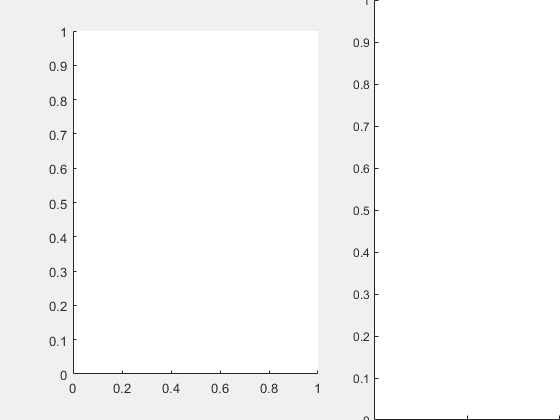

hbox = uix.HBoxFlex( 'Parent', f, 'Spacing', 3 );
axes1 = axes( 'Parent', hbox, 'PositionConstraint', 'outerposition' );
axes2 = axes( 'Parent', hbox, 'PositionConstraint', 'innerposition' );
hbox.Widths = [-2, -1];

## Fill the axes

Using the `OuterPosition` axes property (used by the left-hand axes) is the normal mode, and looks good for virtually any plot type. Using the `Position` axes property is only really useful for 2D plots with the axes turned off, such as images.

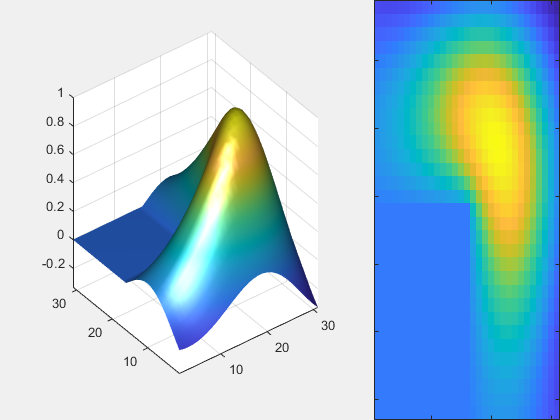

x = membrane( 1, 15 );
surf( axes1, x )
lighting( axes1, 'gouraud' )
shading( axes1, 'interp' )
l = light( 'Parent', axes1 );
camlight( l, 'head' )
axis( axes1, 'tight' )

imagesc( x, 'Parent', axes2 )
set( axes2, 'XTickLabel', [], 'YTickLabel', [] )